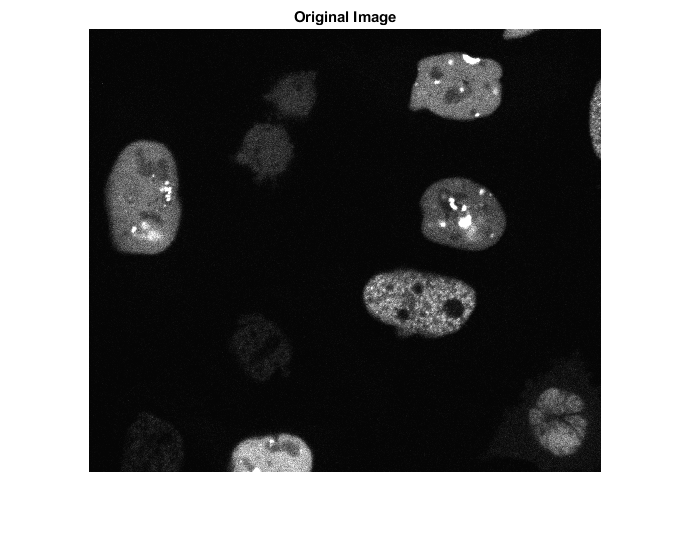

% Implementation of Phase Stretch Transform (PST) in Matlab
% Derived from work of: M. Asghari and Madhuri Suthar, Jalali Lab, Department of Electrical and Computer Engineering,  UCLA

clc  % clear screen
clear all  % clear all variables
close all   % close all figures
addpath('src/'); % script source directory

% New image loading
cell_dataset = cell_dataset('data/Fluo-N3DH-CHO/01/');
% implay(dataset(:,:,1,:), 4);

% Work with a single 3D image for now
Image_orig = cell_dataset(:,:,:,1);

% Repeat the Z axis by 5x, since the voxels are not even in X/Y/Z
% Voxel size (microns): 0.202 x 0.202 x 1.0
% Repeating Z axis by 5x should make the voxel size 0.202 x 0.202 x 0.2
% (good enough)
Image_orig = repelem(Image_orig, 1, 1, 5);

%show the original image
%subplot(1,2,1)
%Image_orig = im2double(Image_orig(:,:,:));
imshow(Image_orig(:,:,1))
title('Original Image') % convert the grayscale image do a 2D double array

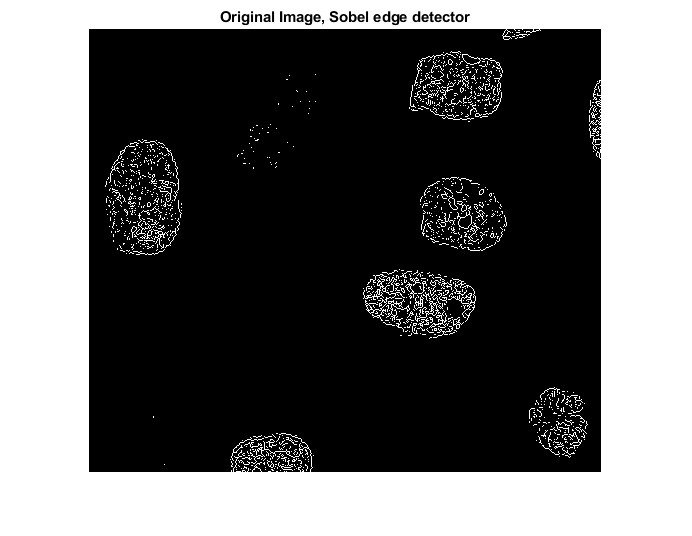

%Image_orig=double(Image_orig);

% MK: Show edges using 1st order Sobel edge detector kernel
figure;
edge(Image_orig(:,:,1), 'sobel');
title('Original Image, Sobel edge detector');

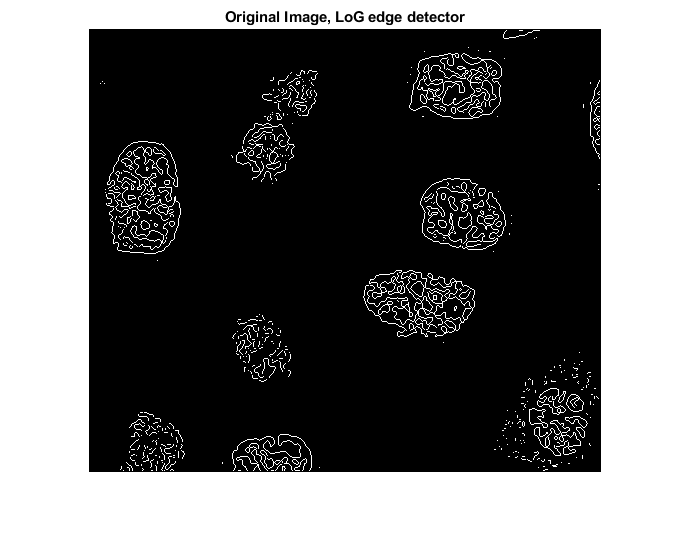

figure;
edge(Image_orig(:,:,1), 'log');
title('Original Image, LoG edge detector');

figure;

% low-pass filtering (also called localization) parameter
handles.LPF=0.15; % Gaussian low-pass filter Full Width at Half Maximum (FWHM) (min:0 , max : 1)

% PST parameters
handles.Phase_strength=0.48;  % PST  kernel Phase Strength
handles.Warp_strength=12.48;  % PST Kernel Warp Strength

% Thresholding parameters (for post processing)
handles.Thresh_min=-1;  % minimum Threshold  (a number between 0 and -1)
handles.Thresh_max= 0.0019;  % maximum Threshold  (a number between 0 and 1)
handles.Thresh_dark = 1/20; % dark threshold (between 0 and 1)

% Apply PST and find features (sharp transitions)
% [Edge, PST_Kernel]= PST(Image_orig,handles,Morph_flag);

%TODO: Clahe or HE algos before pst contrast step to make cells more visible 

for i = 1:size(Image_orig, 3)
    Image_orig(Image_orig<15)=2;
    Image_orig(:,:,i) = filter2(fspecial('average',2),Image_orig(:,:,i));
    %Image_orig(:,:,i) = filter2(fspecial('average',2),Image_orig(:,:,i));
    
    Image_orig(:,:,i) = medfilt2(Image_orig(:,:,i));
    %Image_orig(:,:,i) = imadjust(Image_orig(:,:,i));
    %Image_orig(:,:,i) = histeq(Image_orig(:,:,i));
    Image_orig(:,:,i) = adapthisteq(Image_orig(:,:,i), 'ClipLimit', 0.02);
end
Image_orig(:,:,1)

ans = 443×512 uint8 matrix
   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2
   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2   2 

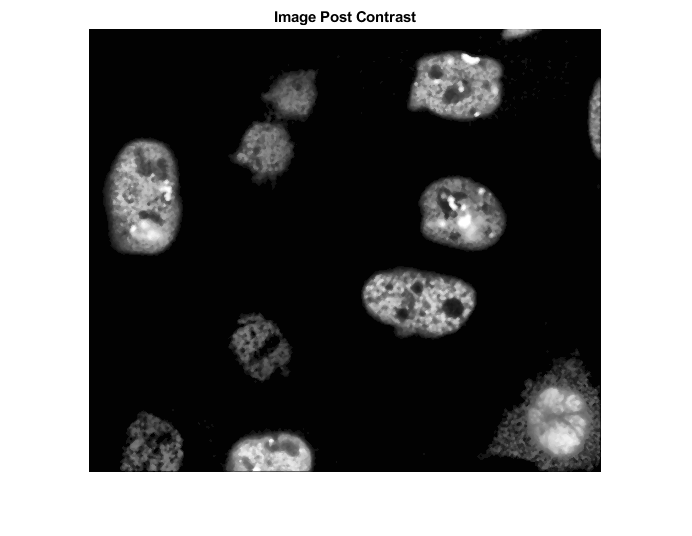

imshow(Image_orig(:,:,1))
title('Image Post Contrast')





[features, PST_Kernel] = PST_ND(Image_orig, handles);
[edge] = PST_post(Image_orig, features, handles);


% MK: Best edges on Z layer 21
refined_edge = edge(:,:,21:25);

% Show and save 'analog' edge output
filename = 't000.tif';
figure;
features_img = features(:,:,1)/max(features, [], 'all')*3

features_img =     0.0059   -0.1191   -0.1772   -0.1734   -0.1628   -0.1590   -0.1582   -0.1580   -0.1579   -0.1579   -0.1579   -0.1579   -0.1579   -0.1579   -0.1579   -0.1579   -0.1579   -0.1579   -0.1579   -0.1579   -0.1578   -0.1578   -0.1576   -0.1572   -0.1564   -0.1546   -0.1498   -0.1362   -0.0955    0.0070    0.1736    0.3108    0.3649    0.4014    0.4333    0.3982    0.3194    0.2733    0.2121    0.1181    0.0507    0.0247    0.0810    0.2828    0.5326    0.4632    0.1863    0.0743    0.1120    0.1528
   -0.1136   -0.1761   -0.2013   -0.1938   -0.1858   -0.1832   -0.1826   -0.1825   -0.1824   -0.1824   -0.1824   -0.1824   -0.1824   -0.1824   -0.1824   -0.1824   -0.1824   -0.1824   -0.1824   -0.1824   -0.1824   -0.1823   -0.1822   -0.1819   -0.1814   -0.1803   -0.1777   -0.1716   -0.1559   -0.1175   -0.0399    0.0736    0.1972    0.3107    0.3924    0.4078    0.3897    0.4122    0.4538    0.4745    0.4834    0.4759    0.4772    0.5265    0.5737    0.5087    0.3948    0.3581    


% Post proccess features_img
features_img(features_img < 0) = 0;
features_img

features_img =     0.0059         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0070    0.1736    0.3108    0.3649    0.4014    0.4333    0.3982    0.3194    0.2733    0.2121    0.1181    0.0507    0.0247    0.0810    0.2828    0.5326    0.4632    0.1863    0.0743    0.1120    0.1528
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0736    0.1972    0.3107    0.3924    0.4078    0.3897    0.4122    0.4538    0.4745    0.4834    0.4759    0.4772    0.5265    0.5737    0.5087    0.3948    0.3581    

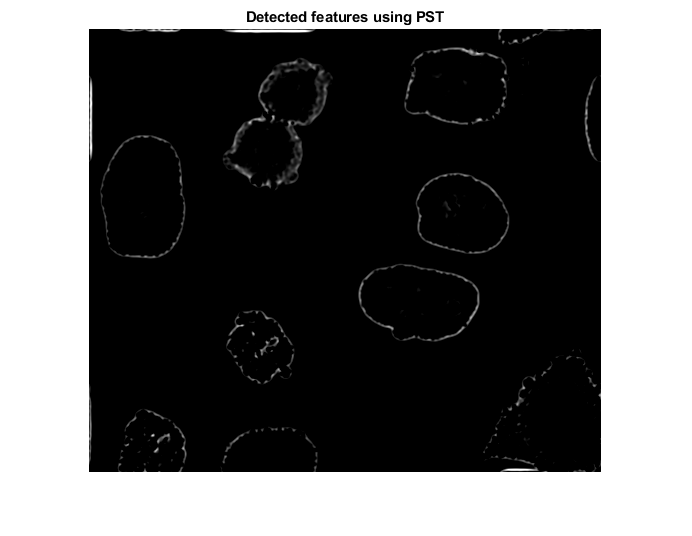


%Attempt to find centroids of blobs
%TODO: Cell segmentation to get better results?
scale_space = dog2(Image_orig(:,:,1), [4, 9, 16, 25, 36, 49, 64]);
scale_space(scale_space <0.1) = 0;
scale_space(scale_space>0.1) = 1;


cc = bwconncomp(scale_space(:,:,4), 26);
stats = regionprops(cc, 'Centroid');
start_cents = [];
for i = 1:size(stats, 1)
    start_cents = [start_cents ; stats(i).Centroid];
end
% prev_size = size(start_cents, 1);
% radius = 5;
% del = 2;
% true_centroids = centroid_reduction(start_cents, radius);
% curr_size = size(true_centroids, 1);
% while prev_size ~= curr_size
%     radius = radius + del;
%     true_centroids = centroid_reduction(true_centroids, radius);
%     prev_size = curr_size;
%     curr_size = size(true_centroids, 1);
% end

imshow(features_img)
title('Detected features using PST')

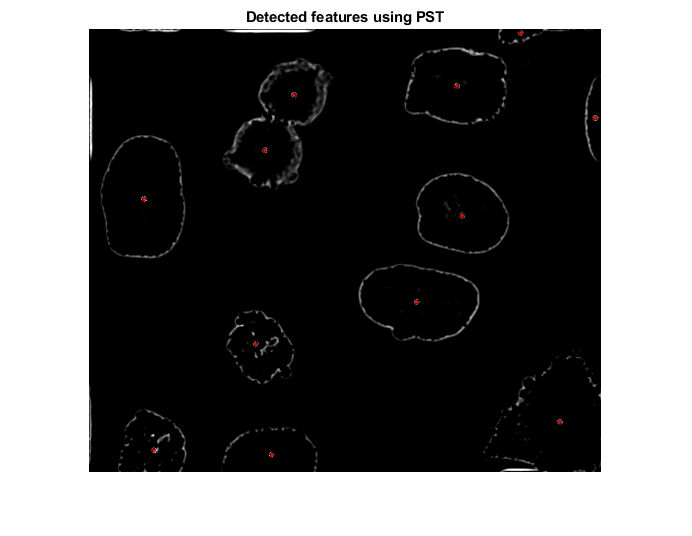

file_and_extension = strsplit(filename,'.');
output_path = char(strcat('data/Test_Images/',file_and_extension(1),'_features.tif'));
imwrite(features_img, output_path);

% Show and save thresholded edges
figure;
imshow(features_img(:,:,1));
radii = ones(size(start_cents, 1), 1) * 1;
viscircles(start_cents(:,[1,2]), radii);
title('Detected features using PST')

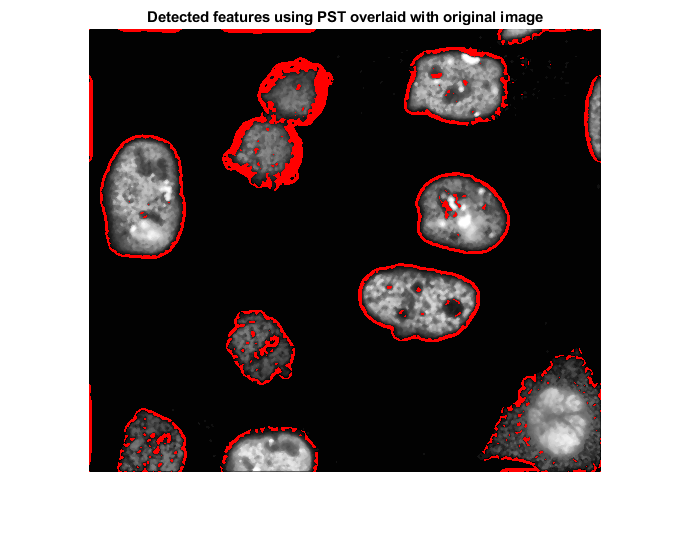

% save the image
file_and_extension=strsplit(filename,'.');
output_path=char(strcat('data/Test_Images/',file_and_extension(1),'_edge.tif'));
imwrite(edge(:,:,1), output_path);
% overlay original image with detected features
overlay = imoverlay(Image_orig, (features_img(:,:,1)), [1 0 0]);
figure;
%imshow(overlay/max(overlay, [], 'all'));
imshow(overlay);
title('Detected features using PST overlaid with original image')

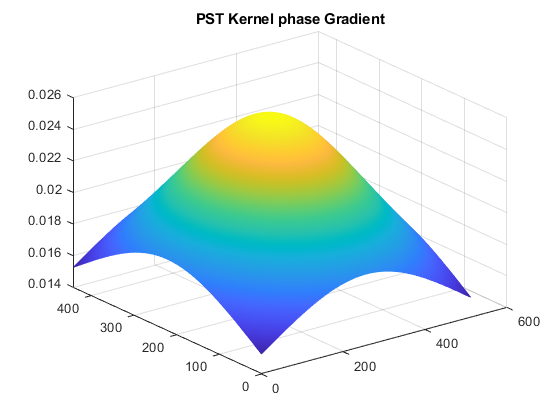

% save the image
output_path=char(strcat('data/Test_Images/',file_and_extension(1),'_overlay.tif'));
imwrite(overlay/max(overlay, [], 'all'), output_path);

% show the PST phase kernel gradient
figure;
[D_PST_Kernel_x, D_PST_Kernel_y, D_PST_Kernel_z]=gradient(PST_Kernel);
mesh(sqrt(D_PST_Kernel_x(:,:,1).^2+D_PST_Kernel_y(:,:,1).^2+D_PST_Kernel_z(:,:,1).^2));
title('PST Kernel phase Gradient');